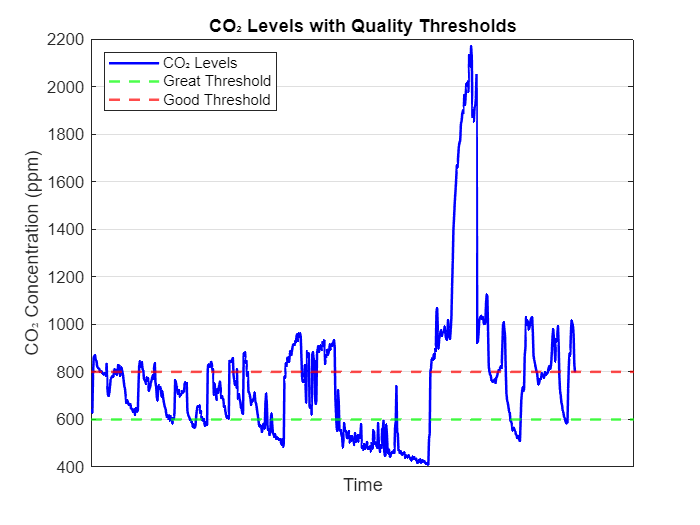

data = 'Dataset.csv';
opts = detectImportOptions(data, 'PreserveVariableNames', true);
columnsCO2 = contains(opts.VariableNames, {'average_co2_concentration', 'average_co2_last_hour'}, 'IgnoreCase', true);
opts.SelectedVariableNames = opts.VariableNames(columnsCO2);
CO2 = readtable(data, opts);

BloomSize = 20000;
k = 5;  
WindowSize = 10000;
thresold = 300;
finalSize = 200;

BloomFilterr = BloomFilter(BloomSize, k);
RecentVals = []; 
FilteredCO2 = [];

entries = height(CO2);
for i = 1:entries
    val = CO2.average_co2_concentration(i);
    if i > WindowSize
        Oldval = RecentVals(1);
        RecentVals(1) = [];
        BloomFilterr = BloomFilterr.remBloom(Oldval);
    end
    if ~BloomFilterr.inBloom(val)
        if i > entries - finalSize
            BloomFilterr = BloomFilterr.addBloom(val);
            FilteredCO2 = [FilteredCO2; val];
        else
            if length(FilteredCO2) >= 2
                last2 = FilteredCO2(end-1:end);
                candidateSet = [last2; val];
                if (max(candidateSet) - min(candidateSet)) > thresold
                    RecentVals = [RecentVals; val];
                    continue;
                end
            end
            BloomFilterr = BloomFilterr.addBloom(val);
            FilteredCO2 = [FilteredCO2; val];
        end
    end
    RecentVals = [RecentVals; val];
end

Hashes = 100; 
Signatures = [];
for i = 1:length(FilteredCO2)
    signature = MinHashs.minHash(FilteredCO2(i), Hashes);
    Signatures = [Signatures; signature];
end

SimilarityM = zeros(length(FilteredCO2));
for i = 1:length(FilteredCO2)
    for j = 1:length(FilteredCO2)
        SimilarityM(i, j) = MinHashs.similarity(Signatures(i, :), Signatures(j, :));
    end
end

n = min([length(FilteredCO2), length(SimilarityM)]);
features = FilteredCO2(1:n);
labels = FilteredCO2(1:n);

features = features + eps * randn(size(features));

model = fitcnb(features, labels, 'DistributionNames', 'kernel');

label_map = ["bad", "good", "great"];
naiveBayes = strings(length(features), 2);
for i = 1:length(features)
    current_value = features(i);
    if current_value <= 600
        predicted_category = label_map(3);
    elseif current_value <= 800
        predicted_category = label_map(2);
    else
        predicted_category = label_map(1);
    end
    
    naiveBayes(i, :) = [num2str(current_value), predicted_category];
end
Resultados = array2table(naiveBayes, 'VariableNames', {'Value', 'Classification'});
%Resultados

figure;
plot(1:length(features), features, 'b-', 'LineWidth', 1.5);
hold on;
yline(600, 'g--', 'LineWidth', 1.5);
yline(800, 'r--', 'LineWidth', 1.5);
title('CO₂ Levels with Quality Thresholds');
xlabel('Time');
xticks([])
ylabel('CO₂ Concentration (ppm)');
legend({'CO₂ Levels', 'Great Threshold', 'Good Threshold'}, 'Location', 'northwest');
grid on;
hold off;